# Algorithm Design For Making Handover Decisions in Heterogeneous Wireless Networks

The user defined weights are generated randomly from 1-10. The simulation is for 1000 users. The illustration below is for Criterion 1. The same can be illustrated for criterion 2 and Criterion 3. To do this, only the Criterion Ranges need to be changed in the cell below. And then the rest of the script can be re-run.

### User Defined Weights

% create table with column names
U = table('Size',[1000,3],'VariableNames',{'cost','datarate','delay'}, 'VariableTypes',{'uint8','uint8','uint8'});


% create table with column names
U1 = table('Size',[1000,3],'VariableNames',{'cost','datarate','delay'}, 'VariableTypes',{'uint8','uint8','uint8'});

% Criterion Range [1,4]
U1.cost = randi([1,4],1000,1);%Criterion 1
U1.datarate = randi([1,10], 1000, 1);%Criterion 2
U1.delay = randi([1,10], 1000, 1);%Criterion 3
% create table with column names
U2 = table('Size',[1000,3],'VariableNames',{'cost','datarate','delay'}, 'VariableTypes',{'uint8','uint8','uint8'});

% Criterion Range [4,7]
U2.cost = randi([4,7], 1000, 1); %Criterion 1
U2.datarate = randi([1,10],1000,1); %Criterion 2
U2.delay = randi([1,10], 1000, 1); %Criterion 3

U3 = table('Size',[1000,3],'VariableNames',{'cost','datarate','delay'}, 'VariableTypes',{'uint8','uint8','uint8'});

% Criterion Range [7,10]
U3.cost = randi([7,10], 1000, 1);%Criterion 1
U3.datarate = randi([1,10], 1000, 1);%Criterion 2
U3.delay = randi([1,10],1000,1);%Criterion 3


%Convert Table To Matrix
A1 = table2array(U1);
A2 = table2array(U2);
A3 = table2array(U3);

%Empty Matrix for normalization
B1 = zeros(1000,3);
B2 = zeros(1000,3);
B3 = zeros(1000,3);

## Available RATs and RAT-selection Criteria

There are 3 available RATs namely, 3G, WLAN and 5G. Criteria to be used is Price per MB, Available Datarate, Delay

## Construction Of The Decision Matrix

% generate random values for each term
rat_type = {'3G';'WLAN'; '5G'};
R_datarate = [3;50;100];% Mbps
R_cost = [0.15;0.19;0.5];%Cost in R per MB
R_delay = [100;60;5]; %Latency in ms

% create table with column names
R = table(rat_type, R_cost,R_datarate,R_delay);

D_rat = [R_cost R_datarate R_delay];

%Empty Matrix For Normalization
E = zeros(3,3);


## Normalizing Data

Datarate and Delay = Benefit Attributes

Cost = Cost Attribute

### Normalizing Benefit Attributes


%Decision Matrix
[r_row, r_col] = size(D_rat);
[row, col] = size(A1);

%Datarate
for i = 1:r_row
   E(i,2) = D_rat(i,2) / max(D_rat(:,2));
end

%Delay
for i = 1:r_row
   E(i,3) = min(D_rat(:,3)) / D_rat(i,3);
end


### Normalizing Cost Attributes


%Decision Matrix
for i = 1:r_row
   E(i,1) = min(D_rat(:,1)) / D_rat(i,1);
end

%Normalizing Cost attributes

## Normalise User Weights

%test
for i = 1:row
    for j = 1:col
        B1(i,j) = A1(i,j)/sum(A3(i,:));
        B2(i,j) = A2(i,j)/sum(A3(i,:));
        B3(i,j) = A3(i,j)/sum(A3(i,:));
    end
end

## SAW (Simple Additive Weighting)


% Calculate the weighted sum
s1 = zeros(row,col);
s2 = zeros(row,col);
s3 = zeros(row,col);
for i = 1:row

        %User Weights From [1-3]
        s1(i,1) = (B1(i,1)*E(1,1))+ (B1(i,2)*E(1,2)) + (B1(i,3)*E(1,3));%RAT 1 Score
        s1(i,2) = (B1(i,1)*E(2,1))+ (B1(i,2)*E(2,2)) + (B1(i,3)*E(2,3));%RAT 2 Score
        s1(i,3) = (B1(i,1)*E(3,1))+ (B1(i,2)*E(3,2)) + (B1(i,3)*E(3,3));%RAT 3 Score
        %User Weights From [3-7]
        s2(i,1) = (B2(i,1)*E(1,1))+ (B2(i,2)*E(1,2)) + (B2(i,3)*E(1,3));%RAT 1 Score
        s2(i,2) = (B2(i,1)*E(2,1))+ (B2(i,2)*E(2,2)) + (B2(i,3)*E(2,3));%RAT 2 Score
        s2(i,3) = (B2(i,1)*E(3,1))+ (B2(i,2)*E(3,2)) + (B2(i,3)*E(3,3));%RAT 3 Score
        %User Weights From [7-10]
        s3(i,1) = (B3(i,1)*E(1,1))+ (B3(i,2)*E(1,2)) + (B3(i,3)*E(1,3));%RAT 1 Score
        s3(i,2) = (B3(i,1)*E(2,1))+ (B3(i,2)*E(2,2)) + (B3(i,3)*E(2,3));%RAT 2 Score
        s3(i,3) = (B3(i,1)*E(3,1))+ (B3(i,2)*E(3,2)) + (B3(i,3)*E(3,3));%RAT 3 Score
end



## Effect of Users Weightd [1,4] On RAT Selection For a Certain Criterion

RAT1 = 0; %RAT1 Load
RAT2 = 0;%RAT2 Load
RAT3 = 0; %RAT3 Load

for i = 1:row
    if s1(i,1) == max(s1(i,:))
        RAT1 = RAT1 +1;
    elseif s1(i,2)== max(s1(i,:))
        RAT2 = RAT2 +1;
    elseif s1(i,3) == max(s1(i,:))
        RAT3 = RAT3 +1;
    end
end

y1 = [RAT1 RAT2 RAT3];

## Effect of Users Weightd [3,7] On RAT Selection For a Certain Criterion

RAT1 = 0; %RAT1 Load
RAT2 = 0;%RAT2 Load
RAT3 = 0; %RAT3 Load

for i = 1:row
    if s2(i,1) == max(s2(i,:))
        RAT1 = RAT1 +1;
    elseif s2(i,2)== max(s2(i,:))
        RAT2 = RAT2 +1;
    elseif s2(i,3) == max(s2(i,:))
        RAT3 = RAT3 +1;
    end
end

y2 = [RAT1 RAT2 RAT3];

## Effect of Users Weightd [7,10] On RAT Selection For a Certain Criterion

RAT1 = 0; %RAT1 Load
RAT2 = 0;%RAT2 Load
RAT3 = 0; %RAT3 Load

for i = 1:row
    if s3(i,1) == max(s3(i,:))
        RAT1 = RAT1 +1;
    elseif s3(i,2)== max(s3(i,:))
        RAT2 = RAT2 +1;
    elseif s3(i,3) == max(s3(i,:))
        RAT3 = RAT3 +1;
    end
end

y3 = [RAT1 RAT2 RAT3];

## PLOT Graph Showing Effects

y = [y1; y2; y3]

y =          138          60         802
          27           0         973
           0           0        1000


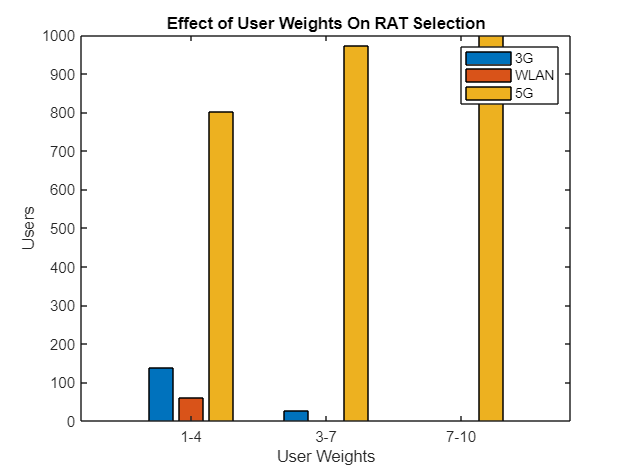

wRange = categorical({'1-4', '3-7', '7-10'});%Weight Ranges
wRange= reordercats(wRange,{'1-4','3-7', '7-10'});
bar(wRange, y)
xlabel('User Weights')
ylabel('Users')
title("Effect of User Weights On RAT Selection")
legend('3G', 'WLAN', '5G')